
start_pos = 300

start_pos = 300

stop_pos = 45

stop_pos = 45

v_max = 10 *6

v_max = 60

a_max = 0.5 * 57.296

a_max = 28.6480

dis = mod(stop_pos - start_pos + 360,360)

dis = 105

inverse = 0;
if mod(start_pos - stop_pos + 360,360) < dis 
    inverse = 1;
    dis = mod(start_pos - stop_pos + 360,360)
end
start_pos = 0;
stop_pos = dis;
ti = 0;

p = [];
w = [];
if dis < (v_max^2)/a_max
    ta = sqrt(dis/a_max);
    T = 2*ta;
    tf = ti+T;
    for t = 0:0.01:T
        if t <= ti+ta
            p = [p start_pos + 1/2*a_max*(t-ti)^2];
            w = [w a_max*(t-ti)];
        else
            p = [p stop_pos-1/2*a_max*(tf-t)^2];
            w = [w a_max*(tf-t)];
        end
    end
else
    T = (dis*a_max + v_max^2)/(a_max*v_max);
    ta = v_max/a_max;
    tf = ti+T;
    for t = 0:0.01:T
        if t <= ti+ta
            p = [p start_pos + 1/2*a_max*(t-ti)^2];
            w = [w a_max*(t-ti)];
        elseif t < tf-ta
            p = [p start_pos + a_max*ta*(t-ti-ta/2)];
            w = [w a_max*ta];
        else
            p = [p stop_pos-1/2*a_max*(tf-t-ti)^2];
            w = [w a_max*(tf-t)];
        end
    
    end
end

if inverse
    p = p*-1;
end

t = (0:0.01:T)';
T

T = 3.8289

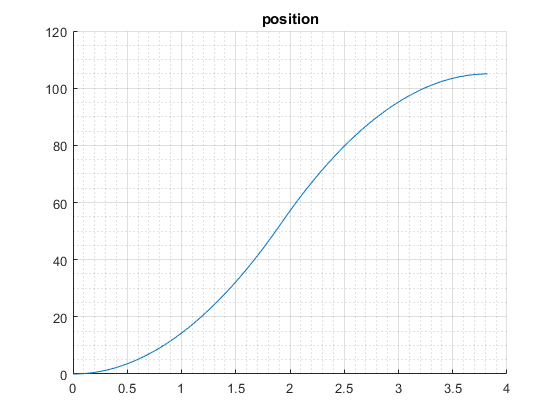

hold on
grid on
grid minor
title('position');
plot(t,p);

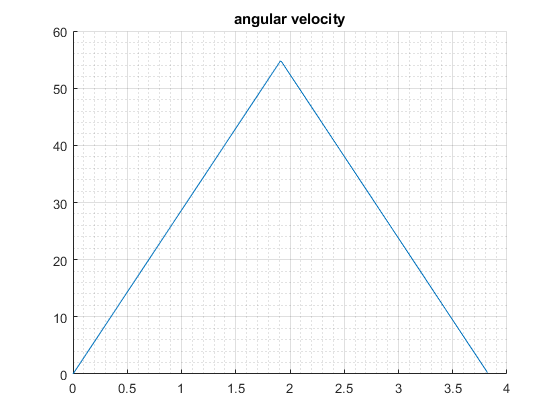


figure
%w = diff(p)/0.01;
hold on
grid on
grid minor
title('angular velocity');
%plot(t(1:end-1),w);
plot(t,w);

max_angular_velocity = max(w)

max_angular_velocity = 54.7177

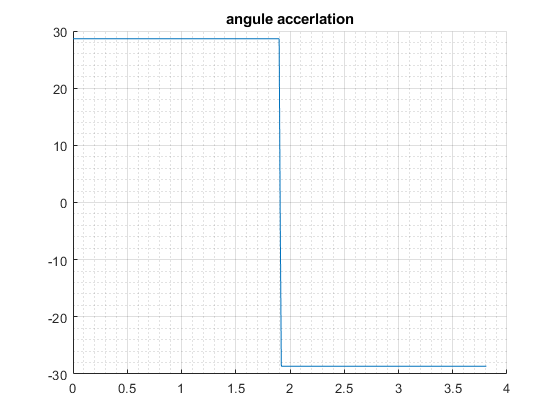


figure
a = diff(w)/0.01;
hold on
grid on
grid minor
title('angule accerlation');
%plot(t(1:end-2),a);
plot(t(1:end-1),a);

max_angular_accerlation = max(a)

max_angular_accerlation = 28.6480